# **PESTools - Example 007 - Showcase of the available ARPES model curves that can be used for fitting**

## PCC

This example shows all of the curve line-shapes that are available to use when fitting to either ARPES or XPS data obtained from the ADRESS beamline. 

- **For ARPES curves:** **2D** **Gaussian**, **2D** **Lorentzian**, **2D** **Voigt** functions are available.

- The **Fermi-Dirac Distribution** **(FDD)** is also used if necessary for fitting states near the Fermi-edge.

- Using the 2D model curves, band dispersions can be plotted and compared to data.

close all; clear all;
pp = plot_props();

# **The functions used to create 2D curves for ARPES data fitting**

The function 'ARPESCurve()' can be used to call any 2D curve line-shape that is plotted with a particular effective mass and energy.

The option is here to also plot its spin-orbit split component, along with its energy shift and branching ratio.

Using a linear combination of 'ARPESCurve()' outputs, we can then fit to any ARPES band dispersions.

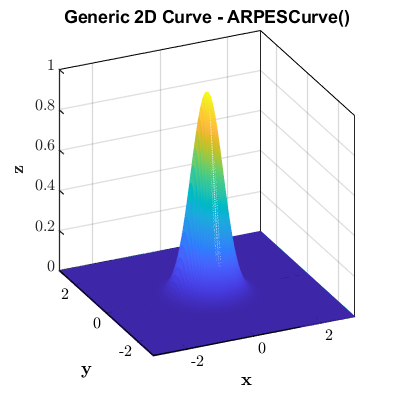

% 1 - Defining the input parameters
xdat = linspace(-3, 3, 1e2);
ydat = linspace(-3, 3, 1e3);
TYPE    = "G2D";    % type of curve to use for fitting. Default: "G2D" ("L2D", "G2DA")
XLOC    = 0.0;      % scalar of the x-location of the 2D PE curve.
YLOC    = 0.0;      % scalar of the y-location of the 2D PE curve.
INT     = 1.0;      % scalar of the peak intensity of 2D PE curve.
FWHM    = 1.0;      % scalar of the FWHM of the 2D PE curve.
ASY     = 1.0;      % scalar of the 2D PE curve asymmetry parameter (scales the FWHM along the y-axis).
% 2 - Calculating the lineshape
zdat    = ARPESCurve(xdat, ydat, TYPE, XLOC, YLOC, INT, FWHM, ASY);
% 3 - Plotting the lineshapes & verifying the FWHM values
fig = figure(); fig.Position(3) = pp.fig4x4(1); fig.Position(4) = pp.fig4x4(2);
hold on;
meshz(xdat, ydat, zdat);
gca_props(); axis square; grid on;
xlabel('$$ \bf  x $$', 'Interpreter', 'latex');
ylabel('$$ \bf  y $$', 'Interpreter', 'latex');
zlabel('$$ \bf  z $$', 'Interpreter', 'latex');
view([-25, 25]);
title('Generic 2D Curve - ARPESCurve()');
axis([min(xdat(:)), max(xdat(:)), min(ydat(:)), max(ydat(:))]);

# **Symmetric Curves**

xdat = linspace(-3, 3, 1e2);
ydat = linspace(-3, 3, 1e2);

## (1) Gaussian 2D Lineshape

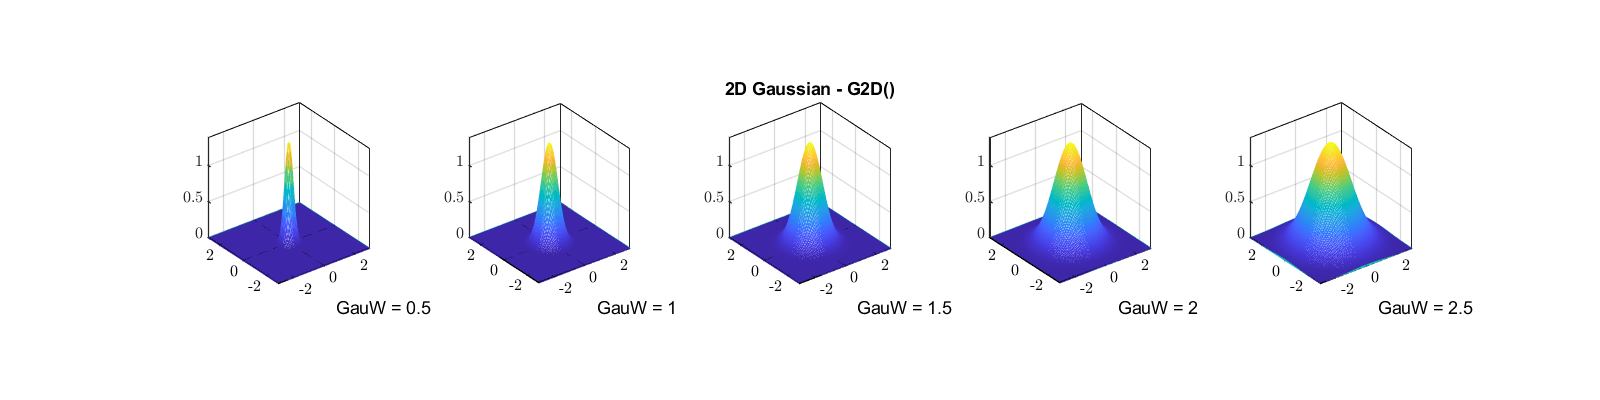

% 1 - Defining the input parameters
peak        = 1.38;         % scalar of the peak beneath the Gaussian.
x0          = 0;            % scalar of the peak position along the x-axis of the Gaussian.
y0          = 0;            % scalar of the peak position along the x-axis of the Gaussian.
fwhm       = 0.5:0.5:2.5;   % scalar of the full-width at half-maximum (FWHM) of the Gaussian.
% 2 - Calculating the 2D lineshape
lgnd = {};
for i = 1:length(fwhm)
    int_gauss{i}    = G2D(xdat, ydat, peak, x0, y0, fwhm(i));
    lgnd{i}         = "GauW = " + string(fwhm(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
fig = figure(); 
fig.Position(3) = 4.*pp.fig4x4(1);
fig.Position(4) = 1.*pp.fig4x4(2);
for i = 1:length(fwhm)
    subplot(1,length(fwhm),i)
    meshz(xdat, ydat, int_gauss{i});
    gca_props(); axis square;
    xlabel(lgnd{i}); 
    if i == 3; title('2D Gaussian - G2D()'); end
end

## (2) Lorentzian 2D Lineshape

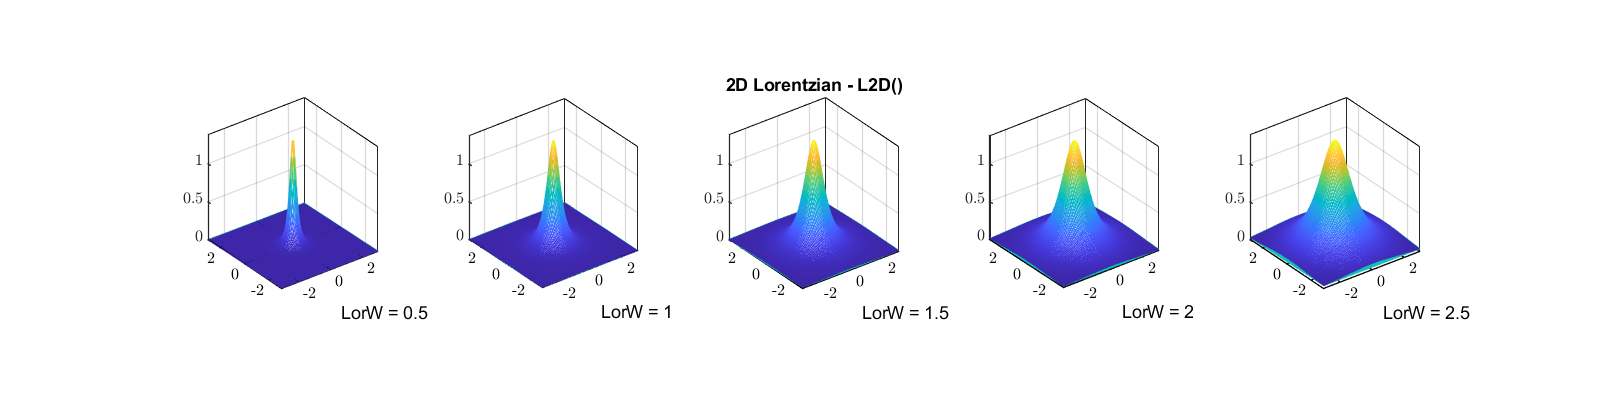

% 1 - Defining the input parameters
peak        = 1.38;         % scalar of the peak beneath the Gaussian.
x0          = 0;            % scalar of the peak position along the x-axis of the Gaussian.
y0          = 0;            % scalar of the peak position along the x-axis of the Gaussian.
fwhm       = 0.5:0.5:2.5;   % scalar of the full-width at half-maximum (FWHM) of the Gaussian.
% 2 - Calculating the 2D lineshape
lgnd = {};
for i = 1:length(fwhm)
    int_lorz{i}    = L2D(xdat, ydat, peak, x0, y0, fwhm(i));
    lgnd{i}         = "LorW = " + string(fwhm(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
fig = figure(); 
fig.Position(3) = 4.*pp.fig4x4(1);
fig.Position(4) = 1.*pp.fig4x4(2);
for i = 1:length(fwhm)
    subplot(1,length(fwhm),i)
    meshz(xdat, ydat, int_lorz{i});
    gca_props(); axis square;
    xlabel(lgnd{i}); 
    if i == 3; title('2D Lorentzian - L2D()'); end
end

# **Asymmetric Curves**

xdat = linspace(-3, 3, 1e2);
ydat = linspace(-3, 3, 1e2);

## (1) Gaussian 2D Lineshape

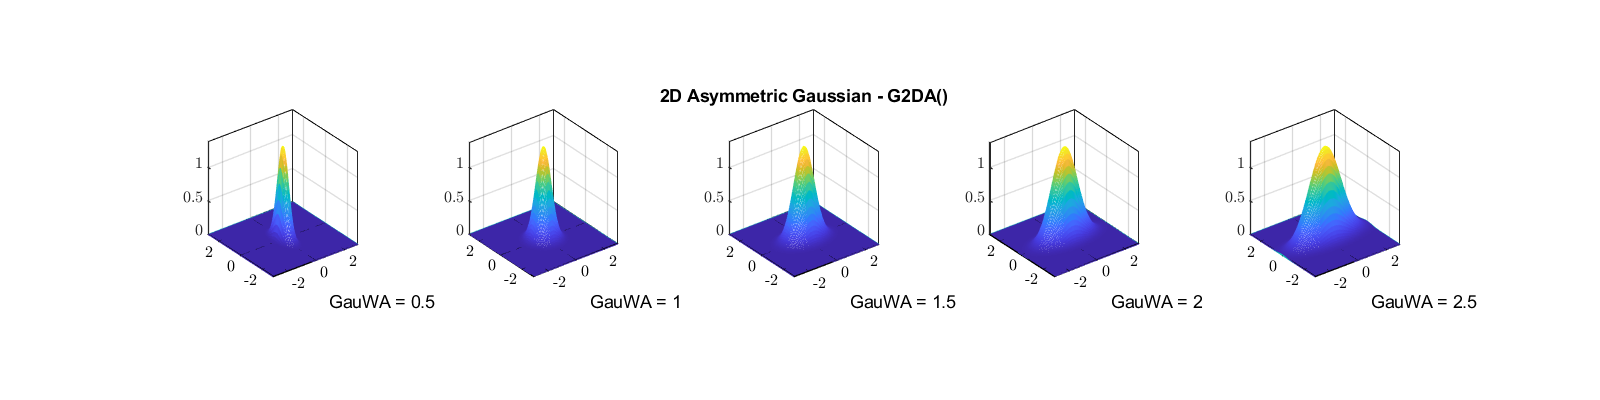

% 1 - Defining the input parameters
peak        = 1.38;         % scalar of the peak beneath the Gaussian.
x0          = 0;            % scalar of the peak position along the x-axis of the Gaussian.
y0          = 0;            % scalar of the peak position along the x-axis of the Gaussian.
xfwhm       = 0.5:0.5:2.5;  % scalar of the full-width at half-maximum (FWHM) of the Gaussian.
yfwhm       = 1;            % scalar of the full-width at half-maximum (FWHM) of the Gaussian.
% 2 - Calculating the 2D lineshape
lgnd = {};
for i = 1:length(xfwhm)
    int_gauss{i}    = G2DA(xdat, ydat, peak, x0, y0, xfwhm(i), yfwhm);
    lgnd{i}         = "GauWA = " + string(xfwhm(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
fig = figure(); 
fig.Position(3) = 4.*pp.fig4x4(1);
fig.Position(4) = 1.*pp.fig4x4(2);
for i = 1:length(xfwhm)
    subplot(1,length(xfwhm),i)
    meshz(xdat, ydat, int_gauss{i});
    gca_props(); axis square;
    xlabel(lgnd{i}); 
    if i == 3; title('2D Asymmetric Gaussian - G2DA()'); end
end